# **JPEG Compression**

In the following steps, an arbitray image is read into 2D matrix then converted into its frequency domain using discrete cosine transform (DCT). After this transformation, specific sort of quantization is applied and the 2D matrix is finally transormed into 1D vector and then run length encoding is applied to that 1D vector. The vector is then exposed to Huffman encoder to get the final stream of bits to be sent through the channel. 

At the decoder side, the coming stream of bits is exposed to the huffman decoder to have the 1D vector back. Run length decoding is then applied and the 1D vector after that is tranformed back to 2D matrix which is the matrix of the frequency domain of the image. At the end, the inverse discrete cosine transform is applied to get back the special domain of the original image. 

**Note**: *In the following report, it is assumed that the quantization tables and the huffman tables are known in both the decoder and encoder.*

In order to evaluate the compression and its quality, two metrics are used for this evaluation; they are:

- Root mean square (RMS) between the original and the decoded images.

- The compression ratio. 

- The structural similarity index

**As initial specifications: **

- **The RMS is needed to be less than 5**

- **The compression ratio is prefered to be around 10:1**

- **The structural similarity must be as near as possible to 0.8**

## **Discrete Cosine Tranform**

- **Generating the DCT basis functions.**

basis = get_basis();

*We can show the basis functions as a prior check for its correctness.*

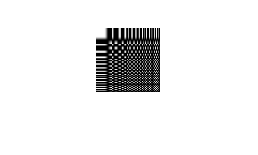

imshow(cell2mat(basis));

This pattern is known for the DCT basis functions hence, the basis functions generations is done correctly.

## **The encoder side**

- **Import the image and convert it to the gray scale.**

img = imread('B2DBY.jpg');
img = double(rgb2gray(img));   % convert to grayscale image
% The image is converted to double in order to perform the upcoming
% calculations accuratly.

- **Convert the image dimensions to dimensions divisible by 8**

[img, rows, cols] = convert_dimensions(img,8);
% rows, cols are the new dimensions of the image.

- **Show the image to use in the next steps (JPEG Compression)**

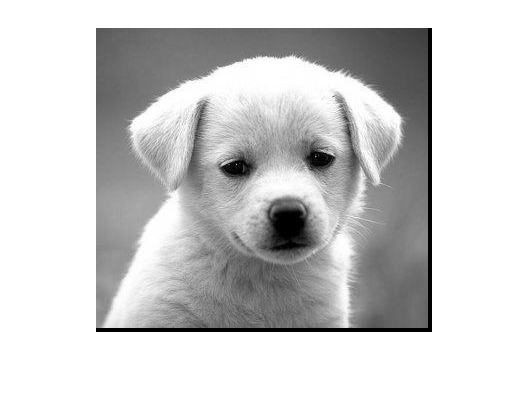

imshow(uint8(img));

- **Perform DCT to the image (for each 8x8 block)**

freq_img = image_dct(img,basis)

freq_img =    91.0000   -1.0201    0.9111    0.0221    0.0442   -0.0183    0.0053   -0.0397   94.0000   -1.0052   -0.0000   -0.0505   -0.0000    0.0506   -0.0000   -0.0011   98.9844   -1.1308    0.8822    0.0242   -0.0663   -0.0544   -0.0067   -0.0299  100.9062   -1.1088    0.8772    0.0257    0.0000   -0.0003   -0.0764    0.0195  101.0000   -1.0966   -0.9688   -0.0091   -0.0442    0.0517   -0.0292   -0.0418  104.0000   -1.1333    0.0747   -0.0177    0.0442    0.0083    0.0647   -0.0172  106.9844   -1.1282
   -2.1140   -0.0597   -0.0686    0.0504    0.0066    0.0312    0.0887   -0.0036   -2.1707    0.0000    0.0562   -0.0000    0.0795    0.0000   -0.0721   -0.0000   -2.1228    1.6303    0.0407   -0.0424   -0.0433   -0.0770    0.0301   -0.0436   -2.1261    0.0221   -0.0159    0.0078         0   -0.0052    0.0066   -0.0044   -1.0088    0.0317   -0.0266    0.1350    0.0785   -0.0710    0.0960    0.0004   -1.1333    1.2099   -0.0139    0.0408   -0.0413   -0.0169   -0.0433   -0.0986   -2.15

- **Quantize the image - in frequency domain - by both high and low quantization tables.**

**First, I tried the 2 quantization tables mentioned in (S. Smith) [1].**

**For low quantization**

q_low = [ 1 1 1 1 1 2 2  4;
          1 1 1 1 1 2 2  4;
          1 1 1 1 2 2 2  4;
          1 1 1 1 2 2 4  8;
          1 1 2 2 2 2 4  8;
          2 2 2 2 2 4 4  8;
          2 2 2 4 4 8 8  16;
          4 4 4 4 8 8 16 16];
      
quant_img_low =  special_quantize(freq_img,q_low)

quant_img_low =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     2     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0    -2    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

**For high quantization**

 q_high = [1   2   4   8   16  32  64  128;
           2   4   4   8   16  32  64  128;
           4   4   8   16  32  64  128 128;
           8   8   16  32  64  128 128 256;
           16  16  32  64  128 128 256 256;
           32  32  64  128 128 256 256 256;
           64  64  128 128 256 256 256 256;
           128 128 128 256 256 256 256 256];
       
quant_img_high = special_quantize(freq_img,q_high)

quant_img_high =     91    -1     0     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     0     0     0     0     0     0   101    -1     0     0     0     0     0     0   101    -1     0     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

- **Perform run length encoding, after transforming the quantized frequency representation to 1D using the following patteren.**

####                                                     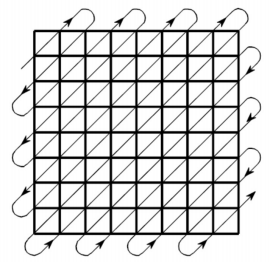

q_img_1D_low=[];
q_img_1D_high=[];

for n_row=1:rows/8
    for n_col=1:cols/8
       n_start_row = 8*(n_row-1)+1; 
       n_start_col = 8*(n_col-1)+1;
       
       block_low = quant_img_low(n_start_row:n_start_row+7, ...
                                                n_start_col:n_start_col+7);
       block_high = quant_img_high(n_start_row:n_start_row+7, ...
                                                n_start_col:n_start_col+7);
       block_1D_low = run_length_encoding(block_low);
       block_1D_high = run_length_encoding(block_high);
       q_img_1D_low = [q_img_1D_low block_1D_low];
       q_img_1D_high = [q_img_1D_high block_1D_high];
    end
end

- **Perform Huffman Encoding**

% For the low quantization
Prs = get_probabilities(q_img_1D_low);
huff_table = jpeg_huffman_table(Prs);
encoded_stream_low = jpeg_huffman_encoder(huff_table,q_img_1D_low)

encoded_stream_low =      1     1     1     0     0     0     0     1     0     0     0     0     0     1     1     0     1     1     0     1     0     0     0     1     0     1     0     1     0     0     1     1     1     1     0     1     1     0     0     1     0     0     1     1     0     0     0     1     1     0


 
 % For the high quantization
Prs = get_probabilities(q_img_1D_high);
table_high = jpeg_huffman_table(Prs);
encoded_stream_high = jpeg_huffman_encoder(table_high,q_img_1D_high)

encoded_stream_high =      0     0     0     0     0     1     1     0     0     0     1     0     1     1     0     1     0     1     1     1     0     0     1     1     1     0     1     1     1     0     1     1     0     0     1     0     1     1     0     1     0     1     1     1     0     0     1     0     0     0


## The decoder side.

- **Perform Huffman Decoding**

 % Decode the two streams
 decoded_stream_low = jpeg_huffman_decoder(huff_table,encoded_stream_low)

decoded_stream_low =     91    -1    -2     0     2     1     0    58    94    -1    -2     0    61    99    -1    -2     0     1     2     1     0    58   101    -1    -2     0     2     1     0     2     2     1     0    54   101    -1    -1     1     0     1    -1     0    58   104    -1    -1     0     1     1     0


 decoded_stream_high = jpeg_huffman_decoder(table_high,encoded_stream_high)

decoded_stream_high =     91    -1    -1     0    61    94    -1    -1     0    61    99    -1    -1     0    61   101    -1    -1     0    61   101    -1    -1     0    61   104    -1    -1     0    61   107    -1    -1     0    61   109    -1    -1     0    61   110     0     1    -1     0    61   111     0     1    -1


- **Recover the image from 1D to 2D matrix with the size of the original image.**

 decoded_img_low  = run_length_decoding(decoded_stream_low,size(img))

decoded_img_low =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     2     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0    -2    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

 decoded_img_high  = run_length_decoding(decoded_stream_high,size(img))

decoded_img_high =     91    -1     0     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     0     0     0     0     0     0   101    -1     0     0     0     0     0     0   101    -1     0     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0

- **Perform the quantization (Low and High)**


  % For low quantization        
    decoded_img_low = inverse_quantization(decoded_img_low,q_low);
  % For low quantization        
    decoded_img_high = inverse_quantization(decoded_img_high,q_high);
   


- **Perform IDCT to the decoded images with both quantizations.**

decoded_img_low = image_idct(decoded_img_low,basis);
decoded_img_high = image_idct(decoded_img_high,basis);

- **Finally! Show the decoded images**

***             With high quantization***

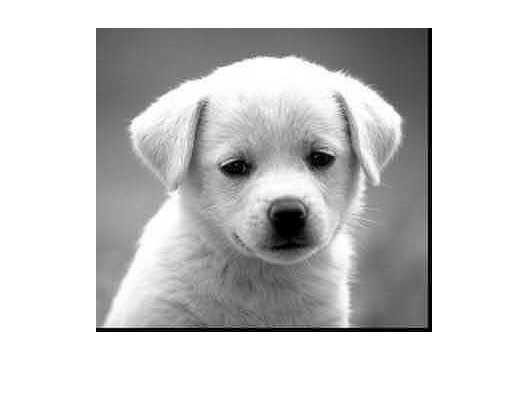

imshow(uint8(decoded_img_high));

***            With low quantization***

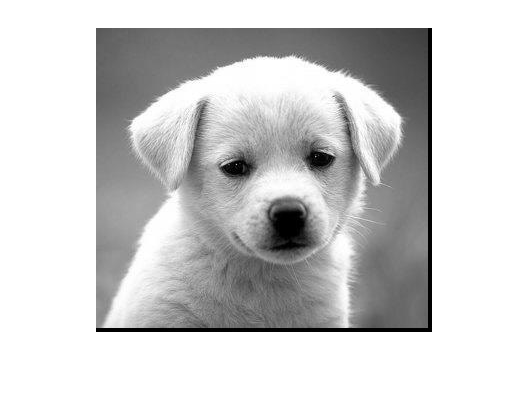

imshow(uint8(decoded_img_low));

- **Evaluation**

**            For low quantization**

 RMS_error = sqrt(sum((img-decoded_img_low).^2,'all')./(rows*cols))

RMS_error = 0.9430

 compression_ratio =(8*rows*cols)/length(encoded_stream_low)

compression_ratio = 5.0799

 ssim_value = ssim(decoded_img_low,img)

ssim_value = 0.9761

 **            For high quantization**

RMS_error = sqrt(sum((img-decoded_img_high).^2,'all')./(rows*cols))

RMS_error = 7.2554

compression_ratio = (8*rows*cols)/length(encoded_stream_high)

compression_ratio = 12.1326

ssim_value = ssim(decoded_img_high,img)

ssim_value = 0.6346

**In low quantization, RMS and SSIM values are suitable however the compression ratio is low.**

**In high quantization, RMS and SSIM values are not accepted however the compression ratio is high.**

***These results are highly sensible and intuitive. ***

**In order to get much more optimized results, we can modifiy the high quantization table by reducing the values in the upper left square in order to have better representation for the lower and the middle frequencies in the image.**

- Hence, the new quantization table is:

     q = [ 1  1   1   4   8   16  32  32;
           1  1   2   8   16  32  64  32;
           1  2   4   16  32  32  64  128;
           4  8   8   32  32  64  128 128;
           8  16  16  32  32  64  128 128;
           16 32  32  64  64  128 128 256;
           32 64  64  64  128 128 256 256;
           32 64  64  128 256 256 256 256];
       
quant_img= special_quantize(freq_img,q)

quant_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     2     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0    -2    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

### **The encoder.**

- **1D transformation and run length encoding**

q_img_1D=[];

for n_row=1:rows/8
    for n_col=1:cols/8
       n_start_row = 8*(n_row-1)+1; n_start_col = 8*(n_col-1)+1;
       block = quant_img(n_start_row:n_start_row+7,n_start_col:n_start_col+7);
       block_1D = run_length_encoding(block);
       q_img_1D = [q_img_1D block_1D];
    end
end

- **Perform Huffman encoding**

Prs = get_probabilities(q_img_1D);
huff_table = jpeg_huffman_table(Prs);
encoded_stream = jpeg_huffman_encoder(huff_table,q_img_1D)

encoded_stream =      1     0     1     1     0     1     1     1     0     1     1     1     0     0     1     1     0     1     0     0     1     1     0     1     0     1     1     1     0     1     0     0     1     1     0     1     0     0     0     1     1     1     0     0     1     0     1     0     1     0


### The decoder

- **Perform Huffman decoding**

decoded_stream = jpeg_huffman_decoder(huff_table,encoded_stream)

decoded_stream =     91    -1    -2     0     2     1     0    58    94    -1    -2     0    61    99    -1    -2     0     1     2     1     0    58   101    -1    -2     0     2     1     0     2     1     0    55   101    -1    -1     1     0     1    -1     0    58   104    -1    -1     0     1     1     0    59


- **Re-establish the 2D image and reverse the run length encoding**

 decoded_img = run_length_decoding(decoded_stream,size(img))

decoded_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     2     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0    -2    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

- **Perform the re-quantization **

 decoded_img = inverse_quantization(decoded_img,q);

- **Perform IDCT**

decoded_img = image_idct(decoded_img,basis);
decoded_img1 = decoded_img; %for saving purposes. 

- **Show the recieved image**

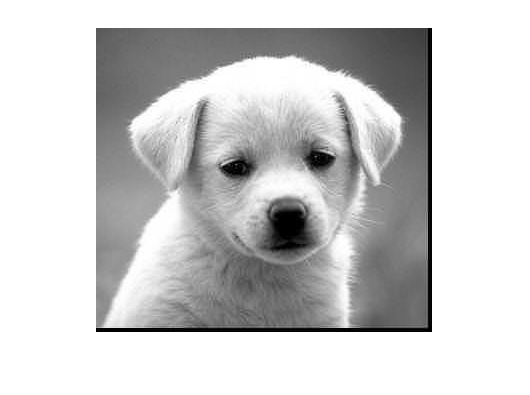

imshow(uint8(decoded_img));

- **Evaluation**

RMS_error = sqrt(sum((img-decoded_img).^2,'all')./(rows*cols))

RMS_error = 6.4571

compression_ratio =(8*rows*cols)/length(encoded_stream)

compression_ratio = 8.9648

ssim_value = ssim(decoded_img,img)

ssim_value = 0.7496

**The new results are approaching the prefered specifications; however, a new modification can be done by increasing more the quantizing values of the high frequencies.  In addition, the values in the upper left edges (for the very lower frequencies) can be also reduced to compromise and approach better RMS and SSIM values.**

- Hence, the new quantization table is:

      
     q = [ 1  1   1   1   2   2   32  32;
           1  4   4   8   32  128 256 256;
           1  4   4   16  64  128 256 256;
           1  8   8   64  64  256 256 256;
           2  16  16  64  128 256 256 256;
           2  32  32  128 128 256 256 256;
           32 64  64  182 256 256 256 256;
           32 64  64  128 256 256 256 256];
       
quant_img= special_quantize(freq_img,q)

quant_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -2     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

### **The encoder.**

- **1D transformation and run length encoding**

q_img_1D=[];

for n_row=1:rows/8
    for n_col=1:cols/8
       n_start_row = 8*(n_row-1)+1; n_start_col = 8*(n_col-1)+1;
       block = quant_img(n_start_row:n_start_row+7,n_start_col:n_start_col+7);
       block_1D = run_length_encoding(block);
       q_img_1D = [q_img_1D block_1D];
    end
end

- **Perform Huffman encoding**

Prs = get_probabilities(q_img_1D);
huff_table = jpeg_huffman_table(Prs);
encoded_stream = jpeg_huffman_encoder(huff_table,q_img_1D)

encoded_stream =      1     0     0     0     0     1     1     0     1     1     1     1     0     1     1     1     0     1     1     0     1     1     0     0     1     0     0     0     1     1     1     1     1     1     0     1     0     1     1     1     1     1     1     0     0     0     1     0     0     1


### The decoder

- **Perform Huffman decoding**

decoded_stream = jpeg_huffman_decoder(huff_table,encoded_stream)

decoded_stream =     91    -1    -2     0     2     1     0    58    94    -1    -2     0    61    99    -1    -2     0     2     1     0    58   101    -1    -2     0     2     1     0     3     1     0    54   101    -1    -1     1     0     1    -1     0    58   104    -1    -1     0    61   107    -1    -2     0


- **Re-establish the 2D image and reverse the run length encoding**

 decoded_img = run_length_decoding(decoded_stream,size(img))

decoded_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -2     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

- **Perform the re-quantization **

decoded_img = inverse_quantization(decoded_img,q);

- **Perform IDCT**

decoded_img = image_idct(decoded_img,basis);
decoded_img2 = decoded_img; %for saving purposes. 

- **Show the recieved image**

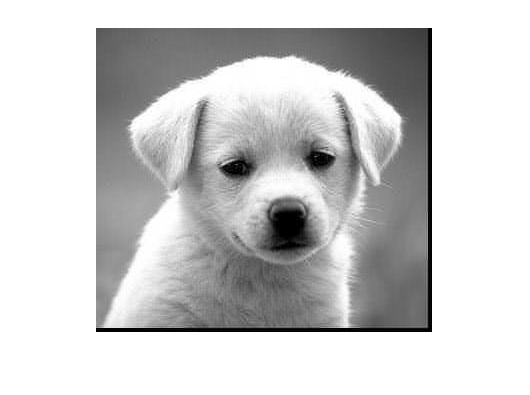

imshow(uint8(decoded_img));

- **Evaluation**

RMS_error = sqrt(sum((img-decoded_img).^2,'all')./(rows*cols))

RMS_error = 6.1627

compression_ratio =(8*rows*cols)/length(encoded_stream)

compression_ratio = 8.1727

ssim_value = ssim(decoded_img,img)

ssim_value = 0.7641

**However, the new results reveals slightly lower RMS error and higher SSIM, it's not worth it to consider this quantization table as the prefered one due to the decrease in the compression ratio which is not toleratable with this slight decrease in error.**

**Till now, the quantization table of the part before the last is the best one. **

- **One more time, the new quantization table is:**

*This time, we test applying more suppression for the higher frequency; the weights in the frequency table for more than half the table is 256 (the maximum values). *

      
     q = [ 1   1   1   1   256 256 256 256;
           1   8   16  32  256 256 256 256;
           1   16  256 256 256 256 256 256;
           1   32  256 256 256 256 256 256;
           256 64  256 256 256 256 256 256;
           256 256 256 256 256 256 256 256;
           256 256 256 256 256 256 256 256;
           256 256 256 256 256 256 256 256];
       
quant_img= special_quantize(freq_img,q)

quant_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -2     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

### **The encoder.**

- **1D transformation and run length encoding**

q_img_1D=[];

for n_row=1:rows/8
    for n_col=1:cols/8
       n_start_row = 8*(n_row-1)+1; n_start_col = 8*(n_col-1)+1;
       block = quant_img(n_start_row:n_start_row+7,n_start_col:n_start_col+7);
       block_1D = run_length_encoding(block);
       q_img_1D = [q_img_1D block_1D];
    end
end

- **Perform Huffman encoding**

Prs = get_probabilities(q_img_1D);
huff_table = jpeg_huffman_table(Prs);
encoded_stream = jpeg_huffman_encoder(huff_table,q_img_1D)

encoded_stream =      1     1     1     1     0     0     0     1     1     1     1     0     0     1     1     0     0     1     0     0     1     1     1     1     0     1     1     0     0     1     1     1     1     1     1     0     1     1     0     1     0     1     1     0     1     1     1     0     0     0


### The decoder

- **Perform Huffman decoding**

decoded_stream = jpeg_huffman_decoder(huff_table,encoded_stream)

decoded_stream =     91    -1    -2     0     2     1     0    58    94    -1    -2     0    61    99    -1    -2     0     2     1     0    58   101    -1    -2     0     2     1     0     3     1     0    54   101    -1    -1     1     0     1    -1     0    58   104    -1    -1     0    61   107    -1    -2     0


- **Re-establish the 2D image and reverse the run length encoding**

 decoded_img = run_length_decoding(decoded_stream,size(img))

decoded_img =     91    -1     1     0     0     0     0     0    94    -1     0     0     0     0     0     0    99    -1     1     0     0     0     0     0   101    -1     1     0     0     0     0     0   101    -1    -1     0     0     0     0     0   104    -1     0     0     0     0     0     0   107    -1
    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0    -2     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

- **Perform the re-quantization **

decoded_img = inverse_quantization(decoded_img,q);

- **Perform IDCT**

decoded_img = image_idct(decoded_img,basis);
decoded_img3 = decoded_img; %for saving purposes. 

- **Show the recieved image**

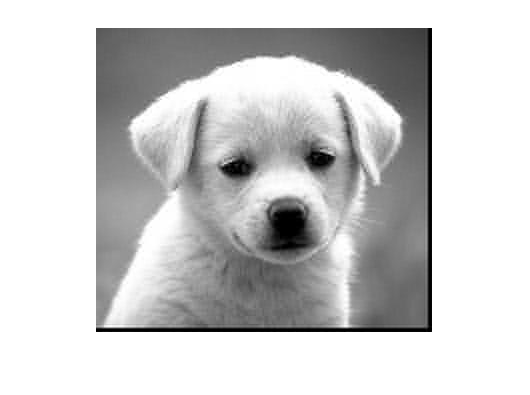

imshow(uint8(decoded_img));

- **Evaluation**

RMS_error = sqrt(sum((img-decoded_img).^2,'all')./(rows*cols))

RMS_error = 7.8229

compression_ratio =(8*rows*cols)/length(encoded_stream)

compression_ratio = 10.8680

ssim_value = ssim(decoded_img,img)

ssim_value = 0.6873

**The compression ratio is really increased in a way that is prefered for the specifications but on the other hand, there's severe increase in the RMS and severe reduction in the SSIM value. This makes the increase in the compression ratio less significant than it can have been. Hence we still stick with the quantization table considered as the best one in the last trial resulting in acceptable combination of image quality metrices and compression ratio. **

- **Here is the final quantization error used for this image.**

     q = [ 1  1   1   4   8   16  32  32;
           1  1   2   8   16  32  64  32;
           1  2   4   16  32  32  64  128;
           4  8   8   32  32  64  128 128;
           8  16  16  32  32  64  128 128;
           16 32  32  64  64  128 128 256;
           32 64  64  64  128 128 256 256;
           32 64  64  128 256 256 256 256];

***The final resultant evaluation for the compressed image is:***

- **RMS = 6.4571                             **(more than the prefrered initial specifications *but acceptable*)

- **Compression Ratio = 8.9648   **(lower than the prefered initial specifications *but acceptable*)

- **SSIM = 0.7496                            **(meets the prefered initial specifications)

- **Save the final compressed image into a file**

%save into a file
imwrite(uint8(decoded_img1),'decoded_dog.png');

## Another Image Trial

In this section, I used the same quantization table in compression of another image as a trial to inspect how this quantization in addition to the whole algorithms/functions behave.

*The following codes are written compressed with no detailed comments.*

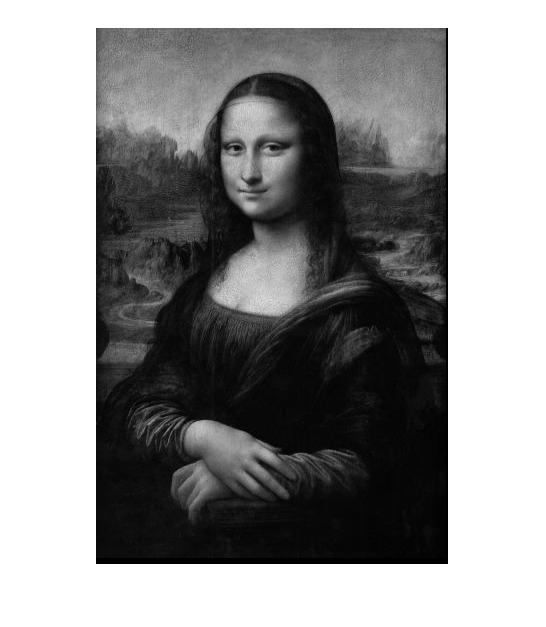

img2 = imread('Mona_Lisa.jpg'); %read the image
img2 = double(rgb2gray(img2));
[img2, rows, cols] = convert_dimensions(img2,8);
imshow(uint8(img2)); %show the img

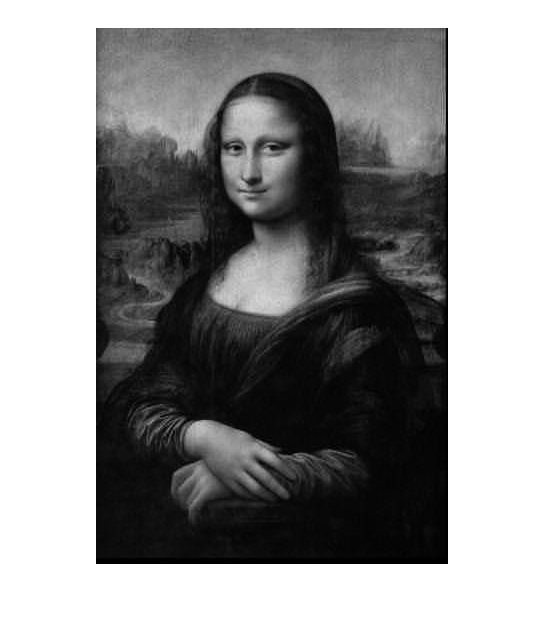

freq_img2 = image_dct(img2,basis); % DCT
quant_img2 = special_quantize(freq_img2,q);
% 1D Transformation and run length encoding
q_img2_1D=[];
for n_row=1:rows/8
    for n_col=1:cols/8
       n_start_row = 8*(n_row-1)+1; n_start_col = 8*(n_col-1)+1;
       block = quant_img2(n_start_row:n_start_row+7,n_start_col:n_start_col+7);
       block_1D = run_length_encoding(block);
       q_img2_1D = [q_img2_1D block_1D];
    end
end
% Huffman Encoding
Prs = get_probabilities(q_img2_1D);
huff_table = jpeg_huffman_table(Prs);
encoded_stream2 = jpeg_huffman_encoder(huff_table,q_img2_1D);
% Huffman Decoding
decoded_stream2 = jpeg_huffman_decoder(huff_table,encoded_stream2);
% run length decoding and 2D transformation
decoded_img_2 = run_length_decoding(decoded_stream2,size(img2));
% Re-Quantization
decoded_img_2 = inverse_quantization(decoded_img_2,q);
% IDCT
decoded_img_2 = image_idct(decoded_img_2,basis);
imshow(uint8(decoded_img_2));

- **Evaluation**

RMS_error = sqrt(sum((img2-decoded_img_2).^2,'all')./(rows*cols))

RMS_error = 4.4108

compression_ratio =(8*rows*cols)/length(encoded_stream2)

compression_ratio = 9.5495

ssim_value = ssim(decoded_img_2,img2)

ssim_value = 0.7348

**The final results for 'Mona Lisa' image, reveal the very good behaviour of the choosen final quantization table on another image resulting in even higher compression ratio with very accepted image quality metrics.**

## References

[1] S. Smith, *The scientist and engineer's guide to digital signal processing*. San Diego, Calif.: California Technical Pub., 1997, p. Ch. 27. 